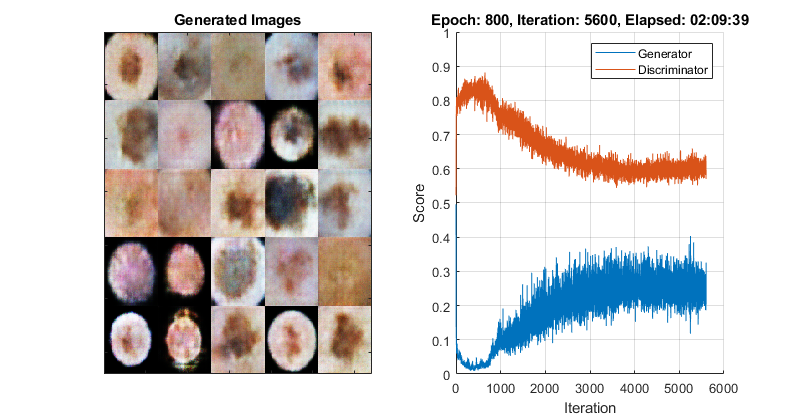

% load Full_GAN_2_64b_800e.mat
% load Full_GAN_256b_600e.mat
% load Mel_GAN_3_16b_800e.mat
% load Mel_GAN_4_128b_600e.mat
load Mel_GAN_5_128b_800e.mat

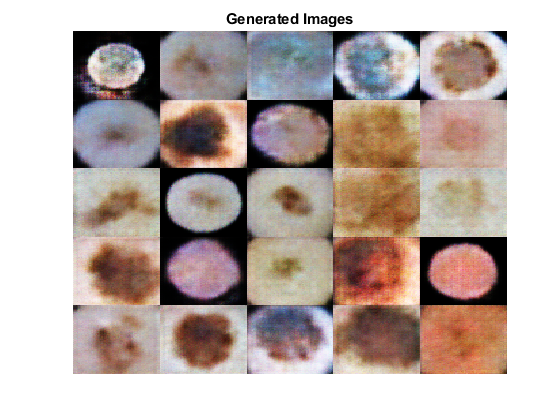

numObservations = 25; % change observations for number of images to be displayed
ZNew = randn(numLatentInputs,numObservations,'single');
dlZNew = dlarray(ZNew,'CB');

if (executionEnvironment == "auto" && canUseGPU) || executionEnvironment == "gpu"
    dlZNew = gpuArray(dlZNew);
end

dlXGeneratedNew = predict(dlnetGenerator,dlZNew);
I = imtile(extractdata(dlXGeneratedNew)); % images in tile format
% I = extractdata(gather(dlXGeneratedNew));   % 1 image
I = rescale(I);
figure
image(I);
axis off
title("Generated Images")